## 1. Creating 'Time' Vector

time = linspace(-1,1,10000);

## 2. Sine Wave Vector

frc1 = 3;
signal1 = sin(2*pi*frc1*time);

## 3. Cos Wave Vector

frc2 = 6;
signal2 = cos(2*pi*frc2*time);

## 4. Sampling frequency (Fs) and Sampling Time(Ts)

Ts = mean(diff(time));
Fs = 1/Ts;

Sampling Frequency =  4999.5 Hz

Sampling Time = 0.2 ms

## 5. Graphing

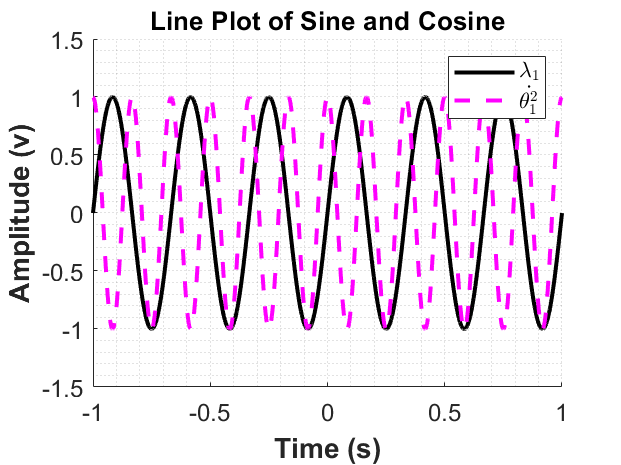

%a. Plot %signal1’ vs ‘time’ in a 2D plot, colour= black, linewidth=2, minor grid.
hold on
plt = plot(time,signal1,'k','LineWidth', 2);
grid minor;
%b. On the same figure, plot %signal2’ vs ‘time’, colour= magenta, linewidth=2, minor grid, style=
%dashed-line
plt2= plot(time, signal2,'--','LineWidth', 2);
plt2.Color = 'magenta';
hold off
%c. Setting the font of axis ticks (not axis label) to size 12
set(gca,'FontSize',12);
%d. Set the x-axis limits to the min and max of the vector %time’
xlim([-1 1]);
%e. Seting the y-axis limits to -1.5 to 1.5 because the largest signal is
%from -1 to 1
ylim([-1.5 1.5]);
%f. Label the x-axis as Time (s), and y-axis as Amplitude (v) with Font size 14, Bold
title('Line Plot of Sine and Cosine');
xlabel('Time (s)','fontweight', 'bold', 'fontsize', 14);
ylabel('Amplitude (v)','fontweight', 'bold', 'fontsize', 14);
%g. Display the legend of the two signals and call signal1 𝜆1 and signal2Θ̇
legend('$$ \lambda_1 $$', '$\dot{\theta_1^2}$', 'Interpreter','latex');
%h. Automatically save the output figure in svg and png formats
saveas(gcf,'Lineplot.png');
saveas(gcf,'Lineplot.svg');